# **Κεφάλαιο 4: Επιλογή Χαρακτηριστικών**

*Τα παραδείγματα και οι ασκήσεις που περιλαμβάνονται στο παρόν σημειωματάριο, βρίσκονται στο βιβλίο: Theodoridis S., Pikrakis A., Koutroumbas K., Cavouras D., Εισαγωγή στην Αναγνώριση Προτύπων με MATLAB, Εκδόσεις Πασχαλίδης, 2011*

## Αποκοπή ακραίων τιμών

### Παράδειγμα 1

Δημιουργήστε $N=100$ σημεία που ακολουθούν μια μονοδιάσταστη Gaussian κατανομή, μέσης τιμής $m=1$ και διασποράς $\sigma^2=0.16$. Ακολούθως να συμπεριληφθούν στο σύνολο σημείων έξι ακραίες τιμές, οι $6,2, -6,4, 6,8, 4,2, 15$.  Σημειώστε ότι η απόσταση κάθε ενός από αυτά τα ακραία σημεία από τη μέση τιμή είναι μεγαλύτερη από $3\sigma$. Οι αριθμοί αυτοί εισάγονται σε τυχαίες θέσεις στο σύνολο σημείων. Στη συνέχεια, χρησιμοποιήστε τον παρακάτω κώδικα για να προσδιορίσετε και εκτυπωσετε τις ακραίες τιμές καθώς και τις θέσεις τους στον πίνακα των σημείων.

close('all');
clear;

% 1. Generate the data set.
randn('seed',0);
m=1; var=0.16;
stdevi=sqrt(var);
norm_dat=m+stdevi*randn(1,100);

%2. Generate the outliers.
outl=[6.2 -6.4 4.2 15.0 6.8];

% 3. Add outliers at the end of the data
dat=[norm_dat';outl'];

% 4. Scramble the data
rand('seed',0); % randperm() below calls rand()
y=randperm(length(dat));x=dat(y);

% 5. Identify outliers and their corresponding indices
times=1; % controls the tolerance threshold
[outliers,Index,new_dat]=simpleOutlierRemoval(x,times);
[outliers Index]

ans =     4.2000    3.0000
    6.8000   49.0000
   15.0000   58.0000
    6.2000   60.0000
   -6.4000   84.0000


## Κανονικοποίηση δεδομένων

### Παράδειγμα 1

Να χρησιμοποιηθούν οι τρεις βασικές κατηγορίες κανονικοποίησης δεδομένων χρησιμοποιώντας ρεαλιστικά δεδομένα που προέρχονται από ιατρικές εικόνες ιστοπαθολογίας. Για τα χαρακτηριστικά των εικόνων θα χρησιμοποιήσουμε τη μέση τιμή και την ασυμμετρία (skewness) των επιπέδων του γκρι εντός πέντε τετραγωνικών περιοχών. Τέτοιες περιοχές είναι γνωστές και ως περιοχές ενδιαφέροντος (Regions of Interest - ROI). Στο παράδειγμα, κάθε εικόνα αποτελείται από έναν αριθμό πυρήνων. Οι πυρήνες της πρώτης εικόνας αντιστοιχούν σε αστροκύττωμα  υψηλού βαθμού κακοήθειας και είναι διαφορετικοί από αυτούς της άλλης εικόνας που αντιστοιχούν σε αστροκύττωμα χαμηλού βαθμού κακοήθειας. Αν δούμε τις τιμές αυτές, παρατηρούμε ότι το εύρος τους διαφέρει σημαντικά μεταξύ των δύο χαρακτηριστικών. Ο στόχος είναι να τις κανονικοποιήσουμε στις δύο κλάσεις.

close('all');
clear;

% 1. File class1.dat and class2.dat contain the values of Table 4.1.
class1=load('class1.dat')';
class2=load('class2.dat')';
% 2. Normalize data in both classes to zero mean and standard deviation equal
% to one, using the normalizeStd.m

[c1_std,c2_std]=normalizeStd(class1,class2)

% 3. Normalize data so that to lie in [-1, 1]
[c1_Mnmx,c2_Mnmx]=normalizeMnmx(class1,class2,-1,1)

c1_std =    -0.4607   -1.0951   -0.6859   -0.6708   -0.9142
    0.4505    0.5468   -1.8381    0.3421   -1.8983


c2_std =     1.1667    1.3043   -0.4963    0.2903    1.5618
    0.5950    0.2156    0.7155    0.6673    0.2036



% 4. Normalize data in [0, 1] using softmax
[c1_Softmax,c2_Softmax]=normalizeSoftmax(class1,class2,0.5)

c1_Mnmx =    -0.5225   -1.0000   -0.6919   -0.6806   -0.8638
    0.7972    0.8710   -0.9539    0.7143   -1.0000


c2_Mnmx =     0.7026    0.8062   -0.5492    0.0429    1.0000
    0.9078    0.6175    1.0000    0.9631    0.6083


## Έλεγχος Υποθέσεων: t-TEST

### Παράδειγμα 1

Υποθέστε ότι ένα χαρακτηριστικό ακολουθεί την κανονική κατανομή σε κάθε κλάση, σε ένα πρόβλημα ταξινόμησης δύο κλάσεων. Οι μέσες τιμές των δύο κατανομών είναι $m_1=8.75$ και $m_2=9$ και η διασπορά τους είναι κοινή και ίση με $\sigma^2=4$

1. Δημιουργήστε δύο διανύσματα δεδομένων, τα $x_1, x_2$ ένα για κάθε κλάση. Το κάθε διάνυσμα περιέχει $N=1000$ δείγματα.

close('all');

c1_Softmax =     0.2847    0.1006    0.2023    0.2072    0.1384
    0.7111    0.7491    0.0247    0.6647    0.0220


c2_Softmax =     0.9116    0.9314    0.2704    0.6412    0.9579
    0.7667    0.6062    0.8070    0.7916    0.6004


clear;

% 1. Generate vectors x1 and x2
randn('seed',0)
m1=8.75;
m2=9;
stdevi=sqrt(4);
N=1000;
x1=m1+stdevi*randn(1,N);
x2=m2+stdevi*randn(1,N);

2. Προσποιηθείτε ότι δεν γνωρίζετε τις μέσες τιμές $m_1, m_2$ καθώς και την διασπορά $\sigma^2$. Γνωρίζετε όμως τις τιμές των δειγμάτων στα διανύσματα $x_1, x_2$ καθώς και το γεγονός ότι προέρχονται από κατανομές ίδιας (αν και άγνωστης) διασποράς. Χρησιμοποιώντας το στατιστικό έλεγχο t-test ελέγξτε εάν οι μέσες τιμές των δύο κατανομών διαφέρουν σημαντικά, θεωρώντας επίπεδο σπουδαιότητας $\rho=0.05$.

% 2. Apply the t-test. Use MATLAB ttest2 function
rho=0.05
[h] = ttest2(x1,x2,rho)

Να επαναληφθεί το βήμα για $\rho=0.001$ και να εξάγετε συμπεράσματα.

% 3. Repeat with rho=0.001
rho=0.001
[h] = ttest2(x1,x2,rho)

### Άσκηση 1

Να επαναληφθεί ο έλεγχος t-test χρησιμοποιώντας για τη διασπορά τις τιμές $1$ και $16$. Να συγκρίνετε και να εξηγήσετε τα αποτελέσματα που προκύπτουν.

## Η καμπύλη Receiver Operating Characteristic (ROC)

### Παράδειγμα 1

Εστω δύο μονοδιάστατες κανονικές κατανομές, με μέσες τιμές $m_1=2, m_2=0$ και διασπορές $\sigma_1^2=\sigma_2^2=1$ αντιστοίχως.

1. Δημιουργήστε $200$ σημεία από κάθε κατανομή

close('all');
clear;

% 1. Generate the two classes
randn('seed',0);
N=200;

rho = 0.0500

m1=2;m2=0;var1=1;var2=1;

h = 1

class1=m1+var1*randn(1,N);
class2=m2+var2*randn(1,N);

2. Σχεδιάστε τα αντίστοιχα ιστογράμματα χρησιμοποιώντας την συνάρτηση *plotHist*

% 2. Plot the histograms of the two classes
plotHist(class1,class2);

rho = 1.0000e-03

3. Υπολογίστε και σχεδιάστε τις αντίστοιχες τιμές για την AUC χρησιμοποιώντας τη συνάρτηση ROC.

% 3. Create the array of class labels

h = 0

classlabels = [1*ones(N,1); -1*ones(N,1)];

% Use the ROC function to calculate and plot the results
[AUC_Value] = ROC([class1 class2]',classlabels,1); % The last argument has been set to 1, because a plot will be generated.

## Ο Λόγος διάκρισης Fisher

### Παράδειγμα 1

Να δημιουργήσετε $N=200$ πενταδιάστατα διανύσματα δεδομένων που ανήκουν σε δύο ισοπίθανες κλάσεις $\omega_1, \omega_2$. Οι κλάσεις μοντελοποιούνται με κανονικές κατανομές με μέσες τιμές $m_1=[1,1,0,6,3]^T$ και $m_2=[11.5,11,10,6.5,4]^T$ και μητρώα συνδιασποράς


$$S_1=\left[ \matrix{ 
0.06 & 0 & 0 & 0 & 0 \cr
0 & 0.5 & 0 & 0 & 0 \cr
0 & 0 & 3 & 0 & 0 \cr
0 & 0 & 0 & 0.001 & 0 \cr
0 & 0 & 0 & 0 & 3
}
\right],
S_2=\left[ \matrix{ 
0.06 & 0 & 0 & 0 & 0 \cr
0 & 0.6 & 0 & 0 & 0 \cr
0 & 0 & 4 & 0 & 0 \cr
0 & 0 & 0 & 0.001 & 0 \cr
0 & 0 & 0 & 0 & 4
}
\right]$$


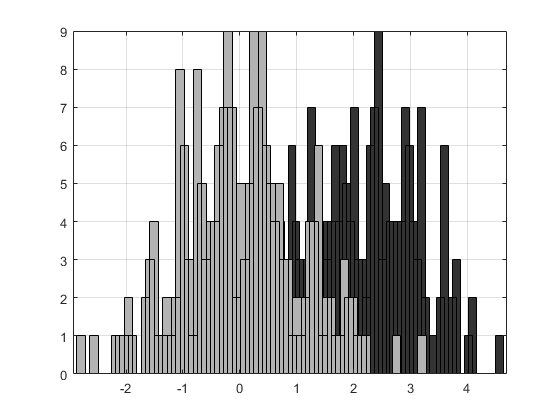

close('all');
clear;

% 1. Generate the data vectors from the first class
N=200;

randn('seed',0)
m1=[1 1 0 6 3];
S1=diag([.06 .5 3 .001 3]);
class1=mvnrnd(m1,S1,fix(N/2))';

% The data vectors of the second class are generated similarly.

m2 = [11.5, 11, 10, 6.5, 4];

S2=diag([.06 .6 4 .001 4]);
class2=mvnrnd(m2,S2,fix(N/2))';

Να υπολογιστεί ο FDR για κάθε ένα από τα πέντε χαρακτηριστικά και να εξαχθούν συμπεράσματα.

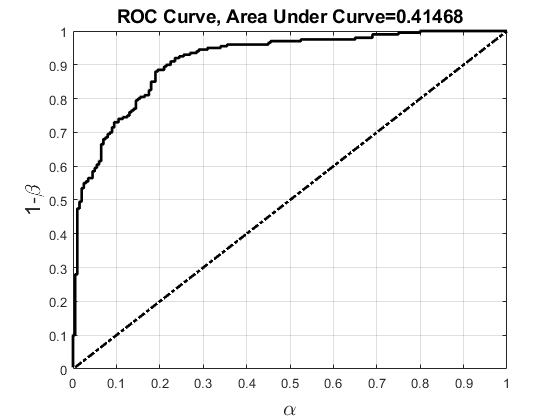

% 2. Compute the FDR for each feature
l=length(m1);
for i=1:l
    FDR(i)= Fisher(class1(i,:)',class2(i,:)');
end

FDR

### Παράδειγμα 2

Σκοπός του παραδείγματος αυτού είναι η χρήση του κριτηρίου Fisher προκειμένου να ιεραρχηθεί ένα πλήθος χαρακτηριστικών ως προς τη διακριτική τους ικανότητα. Τα δεδομένα ανήκουν σε εικόνες ενός ανθρώπινου συκωτιού, που έχει διαγνωστεί ότι πάσχει από κίρρωση (πρώτη εικόνα). Η περίπτωση της δεύτερης εικόνας είναι γνωστή ως λιπώδης εκφύλιση ήπατος. Το ζητούμενο είναι να χρησιμοποιηθεί ένα σύστημα Αναγνώρισης Προτύπων ώστε: με δεδομένη μια εικόνα, να διαγνωστεί αν αυτή ανήκει στον πρώτο ή δεύτερο τύπο ασθένειας. Για αυτό, επιλέγονται περιοχές ενδιαφέροντος ROIs και γίνεται εξαγωγή χαρακτηριστικών στις περιοχές αυτές. Στο δικό μας παράδειγμα θα χρησιμοποιηθούν τα παρακάτω χαρακτηριστικά:

- μέση τιμή επιπέδων γκρι των εικονοστοιχείων εντός της  ROI

- την τυπική απόκλιση

- την ασυμμετρία

- την κύρτωση

Έχουμε διαλέξει $10$ περιοχές σε κάθε εικόνα και αξιοποιούμε τις τιμές που θα συγκεντρωθούν από τις περιοχές αυτές ως δεδομένα εκπαίδευσης. Ο στόχος είναι να υπολογιστεί ο FDR κάθε χαρακτηριστικού και να γίνει ιεράρχιση.

clear('all');
close;

% 1. Load files cirrhoticLiver.dat and fattyLiver.dat
class1=load('cirrhoticLiver.dat')';
class2=load('fattyLiver.dat')';
feature_names={'Mean','Std','Skewness','Kurtosis'};

% 2. Calculate each feature’s FDR
[NumOfFeatures,N]=size(class1);
for i=1:NumOfFeatures
    FDR_value(i)=Fisher(class1(i,:),class2(i,:));
end

% 3. Sort features in descending FDR value
[FDR_value,feature_rank]=sort(FDR_value,'descend');
FDR_value', feature_names(feature_rank)'

## Μέτρα διαχωριστικής ικανότητας μεταξύ κλάσεων

### Απόκλιση

#### Παράδειγμα 1

Έστω πρόβλημα δύο κλάσεων με στατιστικώς ανεξάρτητα χαρακτηριστικά, τα οποία ακολουθούν κανονική κατανομή σε κάθε κλάση. Συγκεκριμένα, η πρώτη (δεύτερη) κλάση μοντελοποιείται με μια κανονική κατανομή, μέσης τιμής $m_1=[3,3]^T, (m_2=[2.3,2.3]^T)$ και μητρώου συνδιασποράς $S_1=0.2I, (S_2=1.9I)$. Δημιουργήστε $100$ σημεία για κάθε κλάση. 

close('all');
clear;

% 1. Generate data for the two classes
m1=[3 3]';S1=0.2*eye(2);

FDR =   930.5209   79.0578   13.7713  107.2842    0.0571


m2=[2.3 2.3]';S2=1.9*eye(2);
randn('seed',0);
class1=mvnrnd(m1,S1,100)';
randn('seed',100);
class2=mvnrnd(m2,S2,100)';

Υπολογίστε την απόκλιση μεταξύ των κλάσεων και σχεδιάστε τα δεδομένα.

% 2. Compute the divergence. Employ the divergence function
Distance=divergence(class1,class2)

% Use function plotData to plot the data
featureNames={'1','2'};
plotData(class1,class2,1:2,featureNames);

#### Άσκηση

Να επαναλάβετε το προηγούμενο παράδειγμα για τις παρακάτω περιπτώσεις:

**Περίπτωση 1:** $m_1=[3,3]^T, S_1=0.2I, m_2=[2.3,2.3]^T, S_2=0.2I$. Δηλαδή ίδια διασπορά και μια μικρή διαφορά στη μέση τιμή.

**Περίπτωση 2: **$m_1=[1,1]^T, S_1=0.2I, m_2=[4,4]^T, S_2=0.2I$. Δηλαδή ίδια διασπορά και μεγάλη διαφορά στη μέση τιμή.

**Περίπτωση 3: **$m_1=[1,1]^T, S_1=0.2I, m_2=[4,4]^T, S_2=1.9I$. Δηλαδή μεγάλη διαφορά στη μέση τιμή αλλά και στη  διασπορά.

### Απόσταση Bhattacharyya και Φράγμα  Chernoff

#### Παράδειγμα

Έστω ένα διδιάστατο πρόβλημα ταξινόμησης σε δύο κλάσεις $\omega_1, \omega_2$ οι οποίες μοντελοποιούνται με κανονικές κατανομές με $m_1=[3,3]^T, S_1=0.2I, m_2=[2.3,2.3]^T, S_2=1.9I$. Πρόκειται για πρόβλημα μικρής διαφοράς στις μέσες τιμές και μεγάλης διαφοράς στις διασπορές. Να υπολογιστεί η απόσταση Bhattacharyya και το φράγμα Chernoff μεταξύ των δύο κλάσεων.

close('all');
clear;

% 1. Generate data for the two classes
m1=[3 3]';S1=0.2*eye(2);
m2=[2.2 2.2]';S2=1.9*eye(2);
randn('seed',0);
class1=mvnrnd(m1,S1,100)';
randn('seed',100);
class2=mvnrnd(m2,S2,100)';

% 2. Compute the Bhattacharyya distance and the Chernoff bound

ans =    13.8893
    1.4897
    0.1055
    0.0210


ans = 4×1 cell array
    {'Mean'    }
    {'Std'     }
    {'Skewness'}
    {'Kurtosis'}


BhattaDistance=divergenceBhata(class1,class2)
ChernoffBound=0.5*exp(-BhattaDistance)

#### Άσκηση 1

Για τις περιπτώσεις της προηγούμενης άσκησης να υπολογίσετε την απόσταση Bhattacharyya και το φράγμα Chernoff μεταξύ των δύο κλάσεων. Σχολιάστε τα αποτελέσματα.

### Μέτρα βασισμένα σε Μητρώα Σκέδασης (Scatter Matrices)

#### Παράδειγμα

Από το παράδειγμα με τα δεδομένα με τις εικόνες ήπατος, θα χρησιμοποιήσουμε το μέτρο $J_3$ για να επιλέξουμε τα καλύτερα χαρακτηριστικά από το σύνολο των χαρακτηριστικών. Θέλουμε να επιλέξουμε εκείνο τον συνδυασμό τριών από τα τέσσερα χαρακτηριστικά, που δίνει την καλύτερη τιμή για το μέτρο $J_3$.

1. Κανονικοποιήστε σε μηδενική μέση τιμή και μοναδιαία διασπορά τις τιμές κάθε χαρακτηριστικού

close('all');
clear;

% 1. Load files “cirrhoticLiver.dat” and “fattyLiver.dat” 
class1=load('cirrhoticLiver.dat')';
class2=load('fattyLiver.dat')';

% Normalize features 
[class1,class2]=normalizeStd(class1,class2);

2. Επιλέξτε το συνδυασμό τριών χαρακτηριστικών που δίνει την καλύτερη $J_3$ τιμή

% 2. Evaluate J3 for the three-feature combination [1, 2, 3], where 1 stands for the mean, 2 for std, and so on
[J]=ScatterMatrices(class1([1 2 3],:),class2([1 2 3],:))

% Work similarly to evaluate the J3 for the remaining three-feature combinations,
% i.e., [1, 2, 4], [1, 3, 4], [2, 3, 4]. Remove the comments as appropriate.
[J]=ScatterMatrices(class1([1 2 4],:),class2([1 2 4],:))

Distance = 5.7233

[J]=ScatterMatrices(class1([1 3 4],:),class2([1 3 4],:))
[J]=ScatterMatrices(class1([2 3 4],:),class2([2 3 4],:))

3. Σχεδιάστε για τον καλύτερο συνδυασμό χαρακτηριστικών, τα σημεία στον τρισδιάστατο χώρο.

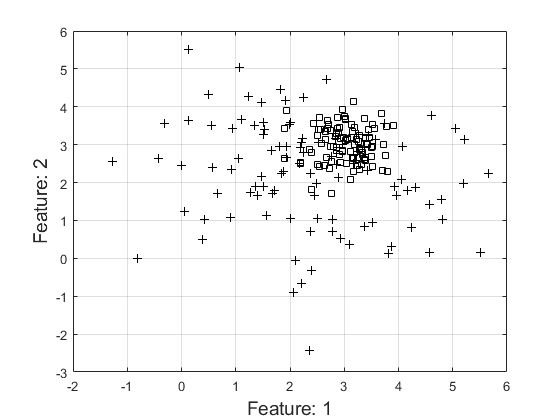

% 3. Plot the results of the feature combination [1, 2, 3]. Use function plotData


featureNames = {'mean','standart dev','skewness','kurtosis'};
plotData(class1,class2,[1 2 3],featureNames);

#### Άσκηση 1

Να επαναλάβετε το πείραμα για όλους τους συνδυασμούς δύο χαρακτηριστικών. Να συγκρίνετε τα αποτελέσματα με αυτά του προηγούμενου παραδείγματος και να γίνει σχολιασμός.

## Επιλογή Υποσυνόλου Χαρακτηριστικών

### Βαθμωτή Επιλογή Χαρακτηριστικών

#### Παράδειγμα 1

Θα χρησιμοποιήσουμε τα δεδομένα από το παράδειγμα με τις εικόνες του ήπατος στο οποία είχαμε δύο κλάσεις και τέσσερα χαρακτηριστικά (μέση τιμή, τυπική απόκλιση, ασυμμετρία και κύρτωση).

1. Κανονικοποιήστε τα χαρακτηριστικά σε μηδενική μέση τιμή και μοναδιαία διασπορά.

close('all');
clear;

% 1. Load files cirrhoticLiver.dat and fattyLiver.dat
class1=load('cirrhoticLiver.dat')';
class2=load('fattyLiver.dat')';

% Normalize and rank the features using the FDR criterion 
[class1,class2]=normalizeStd(class1,class2);

2. Χρησιμοποιήστε το κριτήριο  FDR για να ιεραρχήσετε τα χαρακτηριστικά, εξετάζοντας κάθε χαρακτηριστικό ξεχωριστά

[T]=ScalarFeatureSelectionRanking(class1,class2,'Fisher');

3. Εφαρμόστε την τεχνική βαθμωτής επιλογής χαρακτηριστικών για να ιεραρχήσετε τα χαρακτηριστικά. Χρησιμοποιήστε τον λόγο FDR ως κριτήριο $C$. Να τεθεί $\alpha_1=0.2, \alpha_2=0.8$.

% 2. Rank the features using the features’ cross-correlation
featureNames = {'mean','st. dev.','skewness','kurtosis'};

BhattaDistance = 0.3730

a1=0.2;a2=0.8;

ChernoffBound = 0.3443

[p]= compositeFeaturesRanking (class1,class2,a1,a2,T);

% Print out the results 
fprintf('\n Scalar Feature Ranking \n');
for i=1:size(T,1)
    fprintf('(%10s) \n',featureNames{T(i,2)});
end
fprintf('\n Scalar Feature Ranking with correlation \n');
for i=1:size(p,1)
    fprintf('(%10s) \n',featureNames{p(i)});
end

4. Σχολιάστε τα αποτελέσματα.

### Διανυσματική επιλογή χαρακτηριστικών

#### Παράδειγμα 1

Στο παράδειγμα αυτό θα δείξουμε την διαδικασία επιλογής του καλύτερου συνδυασμού στο πλαίσιο της υποβοηθούμενης από υπολογιστή διάγνωσης μαστογραφίας. Κατά την ψηφιακή επεξεργασία εικόνων μαστού που έχουν ληφθεί με τεχνική ακτίνων Χ, παρατηρούνται μικροασβεστώσεις, συγκέντρωση λευκών κηλίδων που αποτελούνται από εναποθέσεις ασβεστίου στους ιστούς του μαστού. Συχνά κατά τη διάγνωση θεωρούνται ως μη καρκινικές ενδείξεις, αλλά ανάλογα με το σχήμα και την πυκνότητα τους, μπορεί αν υποδεικνύουν καρκινική περίπτωση. Η σπουδαιότητα τους κατά τη διάγνωση του καρκίνου, καθιστά σημαντική την ύπαρξη συστημάτων αναγνώρισης προτύπων που είναι σε θέση να εντοπίζουν την παρουσία μικροασβεστώσεων σε μαστογραφίες. Από κάθε περιοχή εξάγουμε τέσσερα χαρακτηριστικά: τη μέση τιμή, την τυπική απόκλιση, την ασυμμετρία και την κύρτωση.

1. Εφαρμόστε την εξαντλητική μέθοδο προκειμένου να επιλέξετε τον καλύτερο συνδυασμό τριών χαρακτηριστικών (από τα τέσσερα διαθέσιμα), σύμφωνα με το μέτρο απόκλισης, την απόσταση Bhattacharyya και το μέτρο $J_3$.

close('all');
clear;

% 1. Load files breastMicrocalcifications.dat and breastNormalTissue.dat
class1=load('breastMicrocalcifications.dat')';
class2=load('breastNormalTissue.dat')';

% Normalize features so that all of them have zero mean and unit variance
[class1,class2]=normalizeStd(class1,class2);


J = 3.9742

% Select the best combination of features using the J3 criterion
costFunction='ScatterMatrices';
[cLbest,Jmax]=exhaustiveSearch(class1,class2, costFunction,[3])
% 2. Form the classes c1 and c2 using the best feature combination

J = 3.9741

c1 = class1(cLbest,:);

J = 3.6195

c2 = class2(cLbest,:);

J = 1.3972

2. Σχεδιάστε τα δεδομένα στον υποχώρο που ορίζουν τα τρία χαρακτηριστικά που επελέγησαν στο βήμα 1.

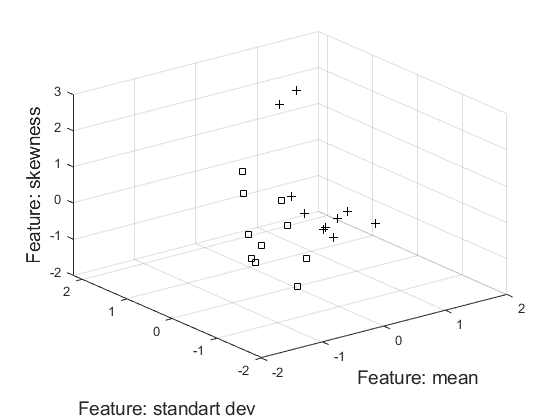

% Plot the data using the plotData function
featureNames = {'mean','st. dev.','skewness','kurtosis'};
plotData(c1,c2,cLbest,featureNames);

#### Άσκηση 1

Υπολογίστε το μέτρο $J_3$ για το συνδυασμό χαρακτηριστικών μέση τιμή, ασυμμετρία και κύρτωση του προηγούμενου παραδείγματος και σχολιάστε τα αποτελέσματα σας σε σχέση με αυτά του παραδείγματος.

### Υποβέλτιστες τεχνικές αναζήτησης

#### Παράδειγμα 1

Ο στόχος του παραδείγματος αυτού είναι να αναδείξει τις (πιθανές) διαφορές, ως προς την ακρίβεια που έχουν οι υποβέλτιστες τεχνικές  SFS, SBS, SFFS συγκρινόμενες με την τεχνική εξαντλήτικής αναζήτησης, την οποία και θεωρούμε ως τεχνική αναφοράς. Το παράδειγμα θα είναι από τον χώρο της ταξινόμησης εικόνων με βάση την υφή, ένα σημαντικό πρόβλημα που βρίσκει εφαρμογή στην αναγνώριση προτύπων.

Έστω ότι έχουμε δύο εικόνες διαφορετικής υφής. Συσχετίζουμε κάθε τύπο υφής με μια ξεχωριστή κλάση. Σε κάθε εικόνα επιλέγουμε $25$ περιοχές. Με αυτόν τον τρόπο προκύπτει ένα σύνολο εκπαίδευσης $50$ προτύπων, που θα αξιοποιηθεί για να επιλεχθεί ο καλύτερος συνδυασμός χαρακτηριστικών. Για τον σκοπό αυτό εξάγουμε τα παρακάτω $20$ χαρακτηριστικά:

- τέσσερα στατιστικά πρώτης τάξης (μέση τιμή, τυπική απόκλιση, ασυμμετρία και κύρτωση κάθε περιοχής)

- δεκαέξι χαρακτηριστικά υφής δεύτερου βαθμού που εξάγονται από τέσσερα μητρώα συνεμφάνισης (co-occurance matrices) που αντιστοιχούν στις κατευθύνσεις $0^o, 90^o, 45^o, 135^
o$. Από κάθε μητρώο συνεμφάνισης εξάγονται η αντίθεση, η συσχέτιση, η ενέργεια και η ομογένεια (τέσσερα χαρακτηριστικά).

Τα χαρακτηριστικά διατάσσονται ώστε τα πρώτα τέσσερα να είναι τα στατιστικά πρώτης τάξης, τα επόμενα τέσσερα η αντίθεση των τεσσάρων μητρώων συνεμφάνισης, τα επόμενα τέσσερα οι συσχετίσεις κ.ο.κ. Τα χαρακτηριστικά μετά την εξαγωγή τους έχουν αποθηκευτεί στα αρχεία *dataClass1.dat, dataClass2.dat*. Από αυτά θα προκύψουν δύο πίνακες διαστάσεων $25\times20$ στο χώρο των μεταβλητών στην MATLAB.

Υποθέτουμε ότι δουλεύουμε σε έναν διδιάστατο χώρο χαρακτηριστικών και ότι θα αξιολογήσουμε την απόδοση τεσσάρων μεθόδων επιλογής χαρακτηριστικών ως προς την ακρίβεια τους προκειμένου να καταλήξουμε στον καλύτερο συνδυασμό δύο χαρακτηριστικών. Θα εφαρμοστούν οι συναρτήσεις  *exhaustiveSearch, SequentialForwardSelection, SequentialBackwardSelection, SequentialForwardFloatingSelection*. Εργαστείτε ως εξής:

1. Κανονικοποιήστε τα χαρακτηριστικά σε μηδενική μέση τιμή και μοναδιαία διασπορά. Μετά ιεραρχήστε τα χαρακτηριστικά με βάση τη μέθοδο βαθμωτής επιλογής, με κριτήριο FDR και λαμβάνοντας υπόψιν το μέτρο ετεροσυσχέτισης μεταξύ χαρακτηριστικών. Να τεθεί $\alpha_1=0.2, \alpha_2=0.8$

close('all');
clear;

% Load the datasets of the two classes
class_1=load('testClass1.dat')';
class_2=load('testClass2.dat')';

% 1. Normalize and rank features in FDR descending order
[class_1,class_2]=normalizeStd(class_1,class_2);
[TFisher]=ScalarFeatureSelectionRanking(class_1,class_2,'Fisher');
[pFisher]= compositeFeaturesRanking(class_1,class_2,0.2,0.8,TFisher);

2. Επιλέξτε τα δεκατέσσερα χαρακτηριστικά που είναι ψηλότερα στην ιεραρχία και εφαρμόστε την τεχνική εξαντλητικής αναζήτησης με το $J_3$ κριτήριο προκειμένου να επιλέξετε τον καλύτερο συνδυασμό δύο χαρακτηριστικών.

% 2. Select the fourteen highest ranked features
NumOfFeats=14;
inds=sort(pFisher,'ascend');
% Use function exhaustiveSearch and the J3 criterion to determine the best combination of two features
[cLbest,Jmax]=exhaustiveSearch(class_1(inds,:),class_2(inds,:),'ScatterMatrices',2);

% Print the results
fprintf('\n Exhaustive Search -> Best of two: ');
fprintf('(%d) ',inds(cLbest));


3. Να επαναλάβετε το παραπάνω ερώτημα για τις μεθόδους SFS, SBS, SFFS. Σχολιάστε τα αποτελέσματα σε σχέση με αυτά του προηγούμενου βήματος.

% 3. Work similarly for the suboptimal searching techniques, i.e., Sequential
% Forward Selection, Sequential Backward Selection and the Floating Search


 Scalar Feature Ranking 


% method

[cLbestSFS,JSFS]=SequentialForwardSelection(class_1(inds,:),class_2(inds,:),'ScatterMatrices',2);

(      mean) 
(  st. dev.) 
(  skewness) 
(  kurtosis) 


fprintf('\n Sequential Forward Selection -> Best of two: ');


 Scalar Feature Ranking with correlation 


fprintf('(%d) ',inds(cLbestSFS));

[cLbestSBS,JSBS]=SequentialBackwardSelection(class_1(inds,:),class_2(inds,:),'ScatterMatrices',2);

(      mean) 
(  kurtosis) 
(  st. dev.) 
(  skewness) 


cLbest =      1     2     3


Jmax = 1.9625

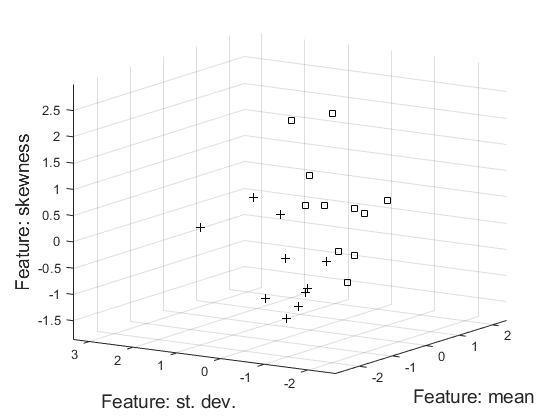


 Exhaustive Search -> Best of two: 

(1) (6) 


 Sequential Forward Selection -> Best of two: 

(1) (5) 


 Sequential Backward Selection -> Best of two: 

(2) (9) 


 Floating Search Method -> Best of two: 

(1) (6) 

fprintf('\n Sequential Backward Selection -> Best of two: ');
fprintf('(%d) ',inds(cLbestSBS));

[cLbestSFFS,JSFFS]=SequentialForwardFloatingSelection(class_1(inds,:),class_2(inds,:),'ScatterMatrices',2);
fprintf('\n Floating Search Method -> Best of two: ');
fprintf('(%d) ',inds(cLbestSFFS));
fprintf('\n');

#### Άσκηση

Να πειραματιστείτε με διαφορετικό πλήθος κορυφαίων στην ιεραρχία χαρακτηριστικών π.χ. με τέσσερα, οκτώ, δέκα και είκοσι χαρακτηριστικά. Σχολιάστε τα αποτελέσματα.

.